Math 155 Final Project

clear;clc;close all;

% import image we want to make a mosaic of
img = imread("royce.jpg");

% get size of original image
[img_x, img_y] = size(img,1,2);

% set desired tile size based off of original image
factor = 15;
tile_x = floor(img_x/factor);
tile_y = floor(img_y/factor);

% import subset of image tiles that will make up the mosaic
%listing = dir(['flowerTiles' '/*.' 'png']);
listing = dir(['Random' '/*.' 'jpeg']);
n = size(listing,1);

for i = 1:n
    imageName = listing(i).name;
    tiles{i} = imread(['Random' '/' imageName],'jpeg');
    tiles{i} = imresize(tiles{i},[tile_x tile_y]);
end

% get size of image tiles
%[tile_x, tile_y] = size(tiles{1},1,2);
%tile_ratio = tile_x/tile_y;

% get size of original image
%[img_x, img_y] = size(img,1,2);
%img_x = tile_ratio * img_y;
%img_y = tile_y/tile_x * img_x;

% resize image to be proportional to image tiles
%img = imresize(img,[img_x img_y]);
%imshow(img)

% set mosaic size as scaled down from original image
%scaling_factor = 5;
%scaled_x = img_x/scaling_factor;
%scaled_y = scaled_x/tile_ratio;

%mosaic_x = floor(scaled_x); % number of tiles across in mosaic
%mosaic_y = floor(scaled_y); % number of tiles down in mosaic

% split image into tiles that will be replaced with image tiles later
%img_tiles = cell(mosaic_x, mosaic_y); % cell array whose entries are the tiles of the original image

mosaic_x = tile_x;
mosaic_y = tile_y;
scaling_factor = factor;

for i=0:mosaic_x-1
    for j=0:mosaic_y-1
        img_tiles{i+1,j+1} = img((i*scaling_factor+1):(i+1)*scaling_factor,(j*scaling_factor+1):(j+1)*scaling_factor,:);
    end
end

% compute average rgb intensity values for each tile in the orignal image
avg_img = zeros(mosaic_x, mosaic_y, 3);
for i=1:mosaic_x
    for j=1:mosaic_y
        current_tile = img_tiles{i,j};
        for rgb = 1:3
            avg_img(i,j,rgb) = mean(mean(current_tile(:,:,rgb)));
        end
    end
end

% compute average rgb intensity values for image tiles
avg_tiles = zeros(n,3);
for i=1:n
    current_tile = tiles{i};
    for rgb = 1:3
        avg_tiles(i,rgb) = mean(mean(current_tile(:,:,rgb)));
    end
end

% find best fit image for each tile on grid
mosaic = cell(mosaic_x,mosaic_y);
for i=1:mosaic_x
    for j=1:mosaic_y
        min_dist = 100000;
        for k = 1:n
            dist = sqrt( ( avg_img(i,j,1) - avg_tiles(k,1))^2 + ( avg_img(i,j,2) - avg_tiles(k,2))^2 + ( avg_img(i,j,3) - avg_tiles(k,3))^2 );
            if dist < min_dist
                min_dist = dist;
                best_img = k;
            end
        end
        % save best image tile into cell array
        mosaic{i,j} = tiles{best_img};
    end
end

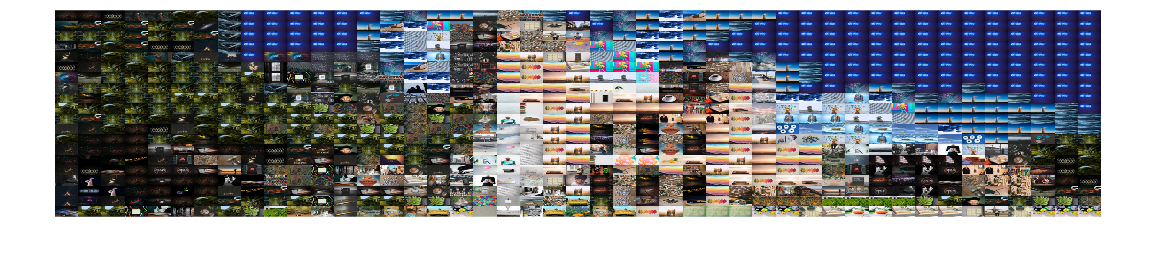

% construct mosaic
final_mosaic = cell2mat(mosaic);
imshow(final_mosaic)